Matlab project :)

**Specific requirements:**

- Introduce the source, format, and background of the data set, what kind of statistical/machine learning task(s) it is originally created for, and websites, papers, or competitions that use the data set.

- Report summary information of the data set, such as #instances, #features (categorical, or numerical), % missing values (if any).

- Visualization of single or small subsets of variables. 

                - Visualization based on 1 - 3 variables at a time should still be performed:

                        - Single categorical variable(s)

                        - General numerical data 

                        - Selected single numerical variables

                        - Selected pairs of variables (both numerical, one numerical + one categorical)

                        - Selected triples of variables (all numerical, two numerical + one categorical)

                        - (if we add reviews) Documents data (refer to data_plotting4.m)

- Feature scaling (if the magnitudes of the variables are very different, normalize them to a common range such as [0,1], or [-1,1])

- Dimension reduction methods to be applied to the data set (for simultaneous visualization of all the numerical variables):  

- Linear, unsupervised: PCA

- Linear, supervised: LDA

- Nonlinear, unsupervised, global: MDS (with any metric except Euclidean) 

- Nonlinear, unsupervised, local: Laplacian Eigenmaps, or another nonlinear one (such as LLE). In the latter case, you must provide a brief, clear description of the algorithm regarding how it works.

Project Steps:

- clean the data

- summary statistics, and visualization of single or small subsets of variables. 

- put all numerical data in a matrix and perform feature scaling

- dimension reduction methods

## **Loading the Data**

clear;
opts = delimitedTextImportOptions("NumVariables", 13);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["App", "Category", "Rating", "Reviews", "Size", "Installs", "Type", "Price", "ContentRating", "Genres", "LastUpdated", "CurrentVer", "AndroidVer"];
opts.VariableTypes = ["string", "categorical", "double", "double", "string", "string", "categorical", "string", "categorical", "categorical", "datetime", "string", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["App", "Size", "Installs", "Price", "CurrentVer", "AndroidVer"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["App", "Category", "Size", "Installs", "Type", "Price", "ContentRating", "Genres", "CurrentVer", "AndroidVer"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "LastUpdated", "InputFormat", "MMMM d, yyyy");
opts = setvaropts(opts, ["Rating", "Reviews"], "ThousandsSeparator", ",");

% Import the data
data = readtable("data/googleplaystore_v2.csv", opts);
clear opts % clear temporary variables

## **Cleaning the data**

Removing Missing Variables

size(data) % 13 vairables, 10841 apps

ans =        10358          13


Missing data by variable

app = sum(ismissing(data.App));
category = sum(ismissing(data.Category));
rating = sum(ismissing(data.Rating));
reviews = sum(ismissing(data.Reviews));
Size = sum(ismissing(data.Size));
installs = sum(ismissing(data.Installs));
type = sum(ismissing(data.Type));
price = sum(ismissing(data.Price));
contentRating = sum(ismissing(data.ContentRating));
genres = sum(ismissing(data.Genres));
lastUpdated = sum(ismissing(data.LastUpdated));
currentVer = sum(ismissing(data.CurrentVer));
androidVer = sum(ismissing(data.AndroidVer));
table(app, category, rating, reviews, Size, installs, type, price, ...
    contentRating, genres, lastUpdated, currentVer, androidVer)

ans = 1×13 table
    app    category    rating    reviews    Size    installs    type    price    contentRating    genres    lastUpdated    currentVer    androidVer
    ___    ________    ______    _______    ____    ________    ____    _____    _____________    ______    ___________    __________    __________

     0        0         1465        1        0         0         1        0            1            0            1             0             0     


clear Size installs price app rating category reviews type contentRating genres lastUpdated currentVer androidVer;
data( any(ismissing(data),2), :) = [];
data(find(string(data.Size)=='Varies with device'),:) = []; % removing weird size
size(data) % size after deleting a ton of variables.

ans =         7424          13


Fixing data types and removing special characters

% data.Sizes
charSize = strtrim(data.Size);
msize = charSize(endsWith(charSize,'M'));
charSize_m = cellstr(string(str2double(string(strrep(msize,'M', '')))*1000));
charSize(endsWith(charSize,'M')) = charSize_m;
SizeOnlyk = strrep(charSize,'k', '');
data.Size_K = SizeOnlyk;
data.Size_K = str2double(string(data.Size_K));

% data.Installs
data.Installs = str2double(strrep(data.Installs,'+',''));

% data.Price
data.Price = str2double(strrep(data.Price,'$',''));

% cleaning up
clear charSize charSize_m msize SizeOnlyk;

Visualization plan

Summary statistics: (top 5 we create plots for)

- maximum price (top 5)

- average price of paid games

- maximum installs (top 5)

- average installs

- average size

- average rating

- top 5 ratings

- average reviews

- top 5 reviews

single categorical variable: (tien) + summary statistics

- category

- type

- content rating

- genre

single numerical variables: (shayna) + summary statistics

- rating

- reviews

- size

- price

- installs

% Ratings plot
histogram(data.Rating,30)
title("Distributions of Ratings",FontSize=14)
xlabel("Ratings",FontSize=12)
ylabel("Count",FontSize=12)
% Reviews plot probably not going to include
histogram(data.Reviews(find(data.Reviews<500000)),20)
title("Distributions of Number of Reviews for apps with less than 500,000",FontSize=14)
xlabel("Number of Reviews",FontSize=12)
ylabel("Count",FontSize=12)
% Size plot
histogram(data.Size_K,20)
title("Distributions of App Size (KB)",FontSize=14)
xlabel("Size (KB)",FontSize=12)
ylabel("Count",FontSize=12)
% Price plot
histogram(data.Price(find(data.Price < 10 & data.Price > 0)),20)
title("Distributions of App Price for Paid Apps Less than $10",FontSize=14)
xlabel("Price",FontSize=12)
ylabel("Count",FontSize=12)
% Most frequent prices
[n,bin] = hist(data.Price,unique(data.Price));
[~,idx] = sort(-n);
n(idx) % The counts

ans =         6877         104          98          61          53          42          28          16          14          12          11           9           8           8           7           6           4           4           3           3           2           2           2           2           2           2           2           2           1           1           1           1           1           1           1           1           1           1           1           1           1           1           1           1           1           1           1           1           1           1


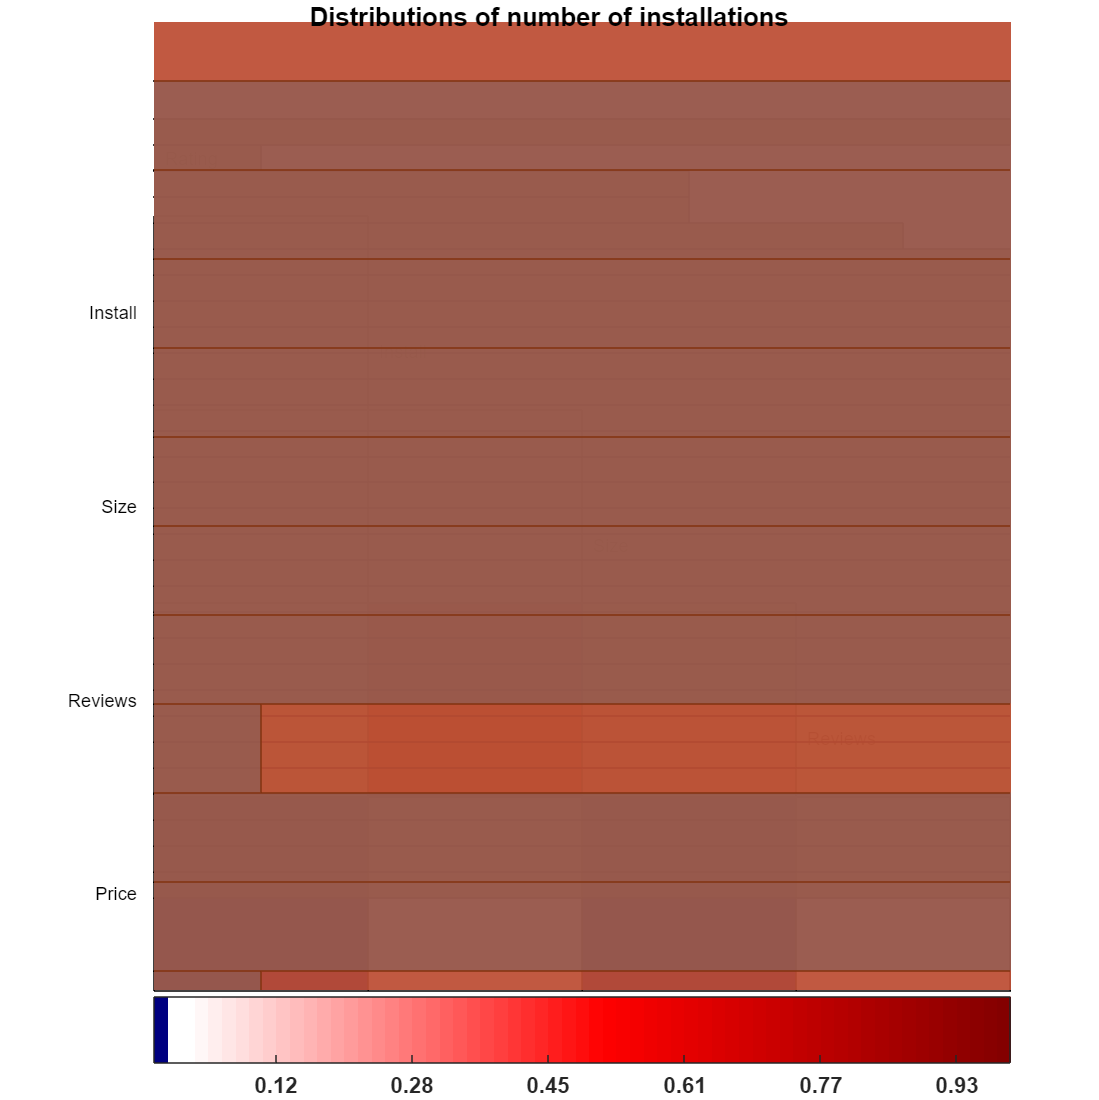


bin(idx); % the prices

% installs plot also terrible
histogram(data.Installs,20) % trying different things
title("Distributions of number of installations",FontSize=14)
xlabel("Number of Installations",FontSize=12)
ylabel("Count",FontSize=12)


G1 = groupcounts(data,'Type');
p = pie(G1.Percent);
pText = findobj(p,'Type','text');
percentValues = get(pText,'String'); 
txt = {'Free: ', 'Paid: '};
combinedtxt = strcat(txt,percentValues'); 
pText(1).String = combinedtxt(1);
pText(2).String = combinedtxt(2);
title('Percentage of Free and Paid Apps', 'fontsize',16);

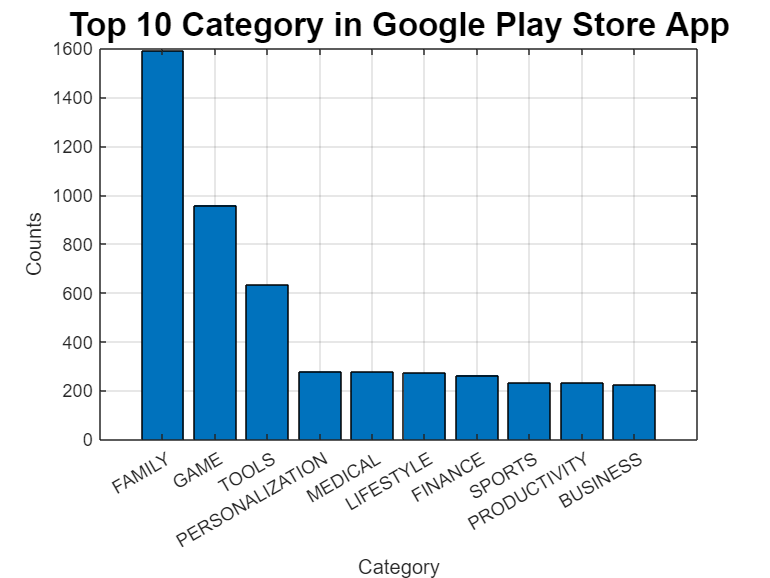

wordcloud(data.Category,'Color','blue');
title('Category Wordcloud')
Category = categories(data.Category);
Count = countcats(data.Category);
category_table = table(Category,Count);
category_table = sortrows(category_table,'Count','descend');
top10_category = category_table(1:10,:);
figure
b = bar(top10_category .Count);
xticklabels(top10_category .Category);
ylabel('Counts')
xlabel('Category')
grid on
title('Top 10 Category in Google Play Store App', 'fontsize', 18)

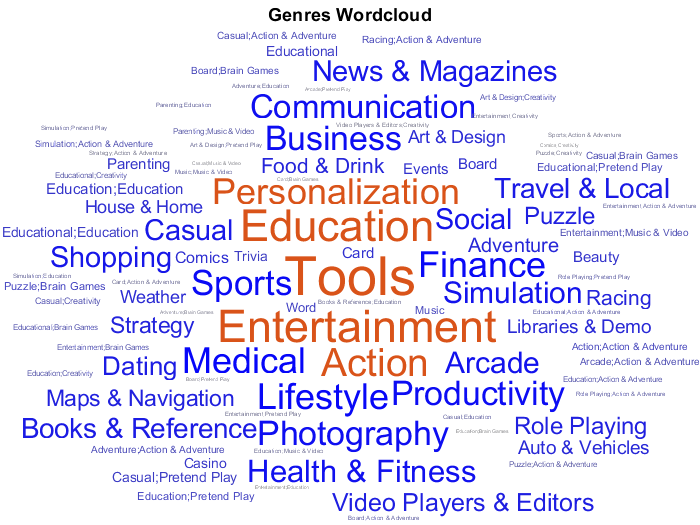

wordcloud(data.Genres,'Color','blue');
title('Genres Wordcloud')

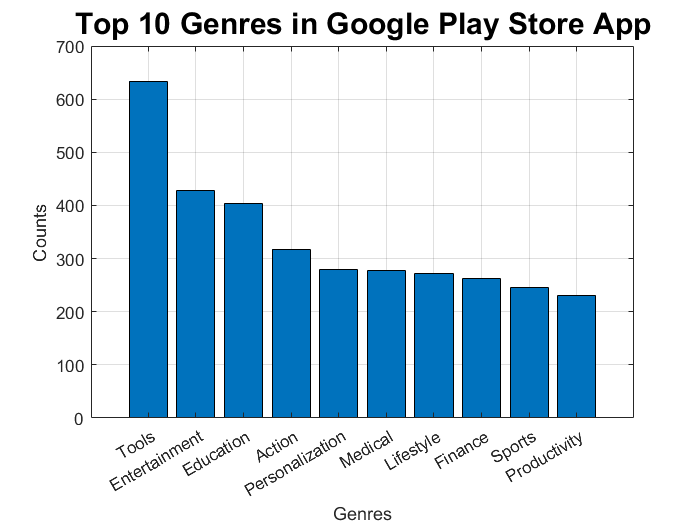

Genres = categories(data.Genres);
Count = countcats(data.Genres);
genres_table = table(Genres,Count);
genres_table = sortrows(genres_table,'Count','descend');
top10_genres = genres_table(1:10,:);
figure
b = bar(top10_genres.Count);
xticklabels(top10_genres.Genres);
ylabel('Counts')
xlabel('Genres')
grid on
title('Top 10 Genres in Google Play Store App', 'fontsize', 18)

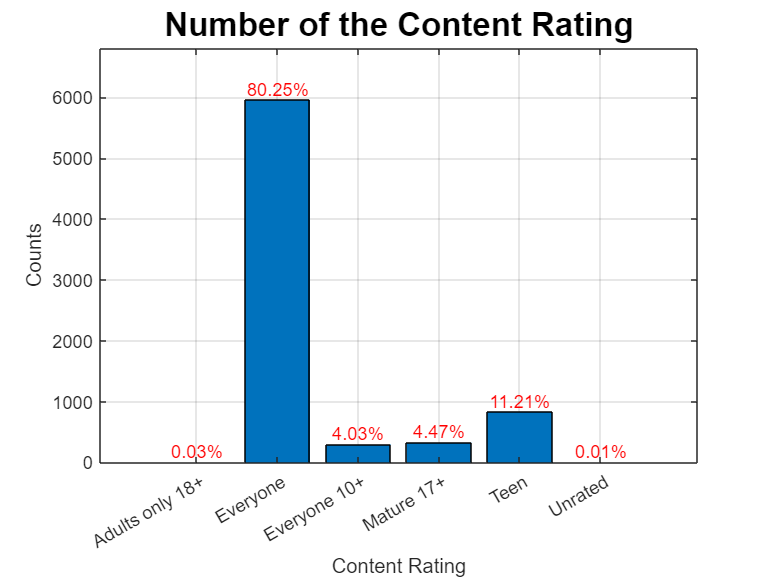

big_category_count = countcats(data.ContentRating);
category_name = categories(data.ContentRating);
conten_Rating_count = groupcounts(data,'ContentRating');
figure
b = bar(big_category_count);
xticklabels(category_name);
ylabel('Counts')
ylim([0 6800])
xlabel('Content Rating')
grid on
title('Number of the Content Rating', 'fontsize', 18)
xtips = b.XEndPoints;
ytips = b.YEndPoints;
labels = string(round(conten_Rating_count.Percent,2)) + '%';
text(xtips,ytips,labels,'Color','red','fontsize',10,'HorizontalAlignment','center','VerticalAlignment','bottom')

#### **Selected pairs of variables both numerical**

- rating

- reviews

- size

- price

- installs

install = data.Installs/1000000000;
review = data.Reviews/1000000;
size = data.Size_K/1000;

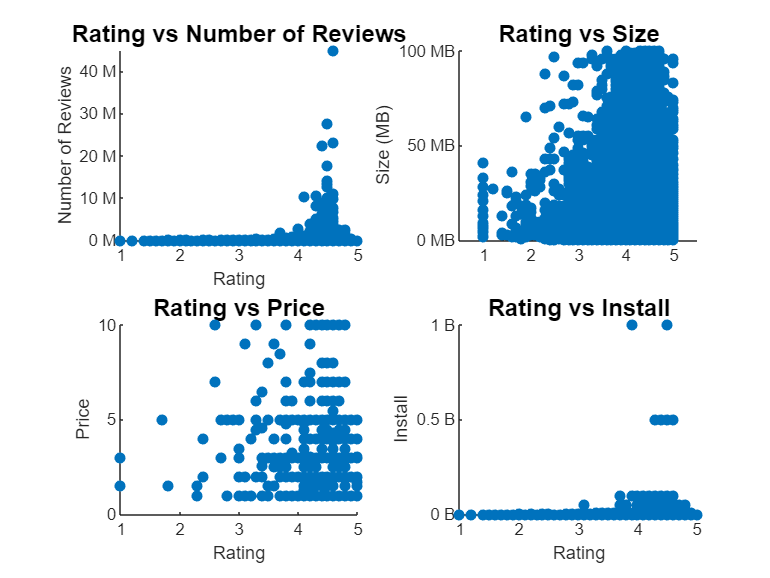

figure;
subplot(2,2,1)
scatter(data.Rating,review,'filled');
ytickformat('%g M')
xlabel('Rating')
ylabel('Number of Reviews')
title('Rating vs Number of Reviews','fontsize', 13)

subplot(2,2,2)
scatter(data.Rating,size,'filled');
title('Rating vs Size','fontsize', 13);
ylabel("Size (MB)")
ytickformat('%g MB')
xlim([0.5 5.5]);

subplot(2,2,3)
scatter(data.Rating(find(data.Price < 10 & data.Price > 0)), data.Price(find(data.Price < 10 & data.Price > 0)),'filled');
xlabel('Rating')
ylabel('Price')
title('Rating vs Price','fontsize', 13);

subplot(2,2,4)
scatter(data.Rating,install,'filled');
ytickformat('%g B')
xlabel('Rating')
ylabel('Install')
title('Rating vs Install','fontsize', 13);

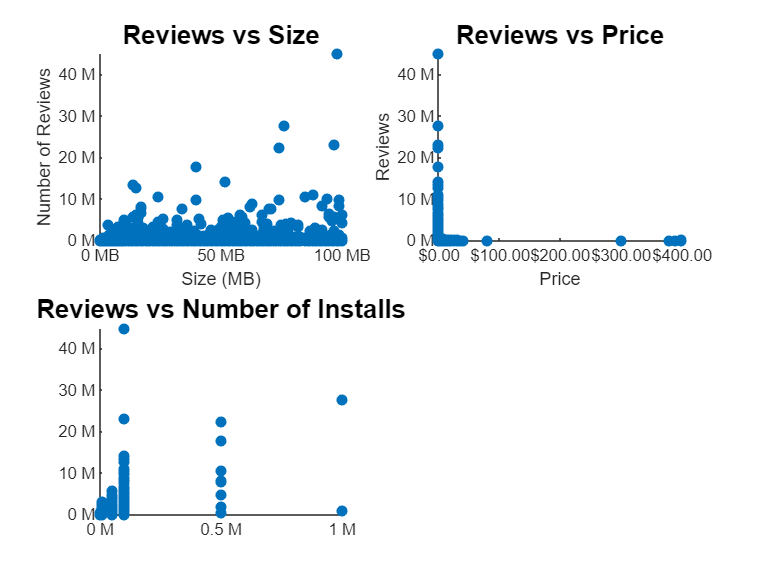

figure;
subplot(2,2,1)
scatter(size,review,'filled');
title('Reviews vs Size','fontsize', 14);
xlabel("Size (MB)")
xtickformat('%g MB')
ytickformat('%g M')
ylabel('Number of Reviews')

subplot(2,2,2)
scatter(data.Price,review,'filled');
xlabel('Price')
xtickformat('usd')
ytickformat('%g M')
ylabel('Reviews')

title('Reviews vs Price','fontsize', 14);

subplot(2,2,3)
scatter(install,review,'filled');
title('Reviews vs Number of Installs','fontsize', 14);
xtickformat('%g M')
ytickformat('%g M')

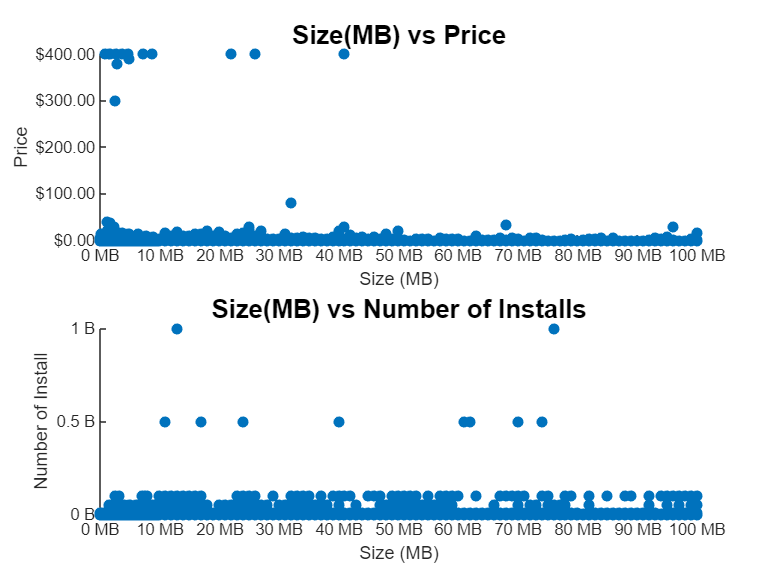

figure;
subplot(2,1,1);
scatter(size,data.Price,'filled');
xlabel('Size (MB)');
xtickformat('%g MB');
ylabel('Price');
ytickformat('usd');
title('Size(MB) vs Price','fontsize', 14);
subplot(2,1,2)
scatter(size,install,'filled');
xlabel('Size (MB)')
xtickformat('%g MB')
ylabel('Number of Install')
ytickformat('%g B')
title('Size(MB) vs Number of Installs','fontsize', 14);

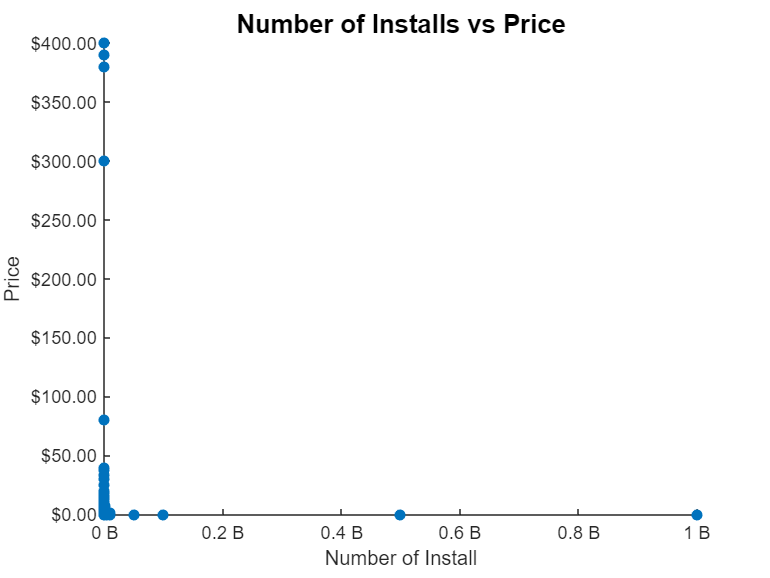

figure;
scatter(install,data.Price,'filled');
xlabel('Number of Install')
xtickformat('%g B')
ylabel('Price')
ytickformat('usd')
title('Number of Installs vs Price','fontsize', 14);

Selected triples of variables all numerical (tien)

num_data = data(:,["Rating","Reviews","Installs", "Price","Size_K"] )

num_data = 7424×5 table
    Rating     Reviews      Installs    Price    Size_K
    ______    __________    ________    _____    ______

     4.1             159     10000        0      19000 
     3.9             967     5e+05        0      14000 
     4.7           87510     5e+06        0       8700 
     4.5      2.1564e+05     5e+07        0      25000 
     4.3             967     1e+05        0       2800 
     4.4             167     50000        0       5600 
     3.8             178     50000        0      19000 
     4.1           36815     1e+06        0      29000 
     4.4           13791     1e+06        0      33000 
     4.7             121     10000        0       3100 
     4.4           13880     1e+06        0      28000 
     4.4            8788     1e+06        0      12000 
     4.2           44

num_data_mat = table2array(num_data)

num_data_mat = 	1.0e+09 *

    0.0000    0.0000    0.0000         0    0.0000
    0.0000    0.0000    0.0005         0    0.0000
    0.0000    0.0001    0.0050         0    0.0000
    0.0000    0.0002    0.0500         0    0.0000
    0.0000    0.0000    0.0001         0    0.0000
    0.0000    0.0000    0.0001         0    0.0000
    0.0000    0.0000    0.0001         0    0.0000
    0.0000    0.0000    0.0010         0    0.0000
    0.0000    0.0000    0.0010         0    0.0000
    0.0000    0.0000    0.0000         0    0.0000


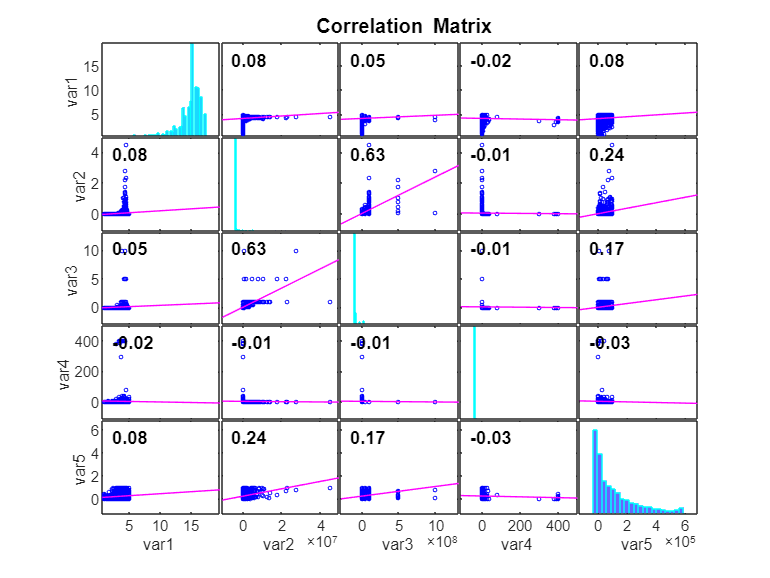

R =     1.0000    0.0805    0.0544   -0.0219    0.0820
    0.0805    1.0000    0.6320   -0.0100    0.2401
    0.0544    0.6320    1.0000   -0.0106    0.1670
   -0.0219   -0.0100   -0.0106    1.0000   -0.0268
    0.0820    0.2401    0.1670   -0.0268    1.0000


R = corrplot(num_data_mat)

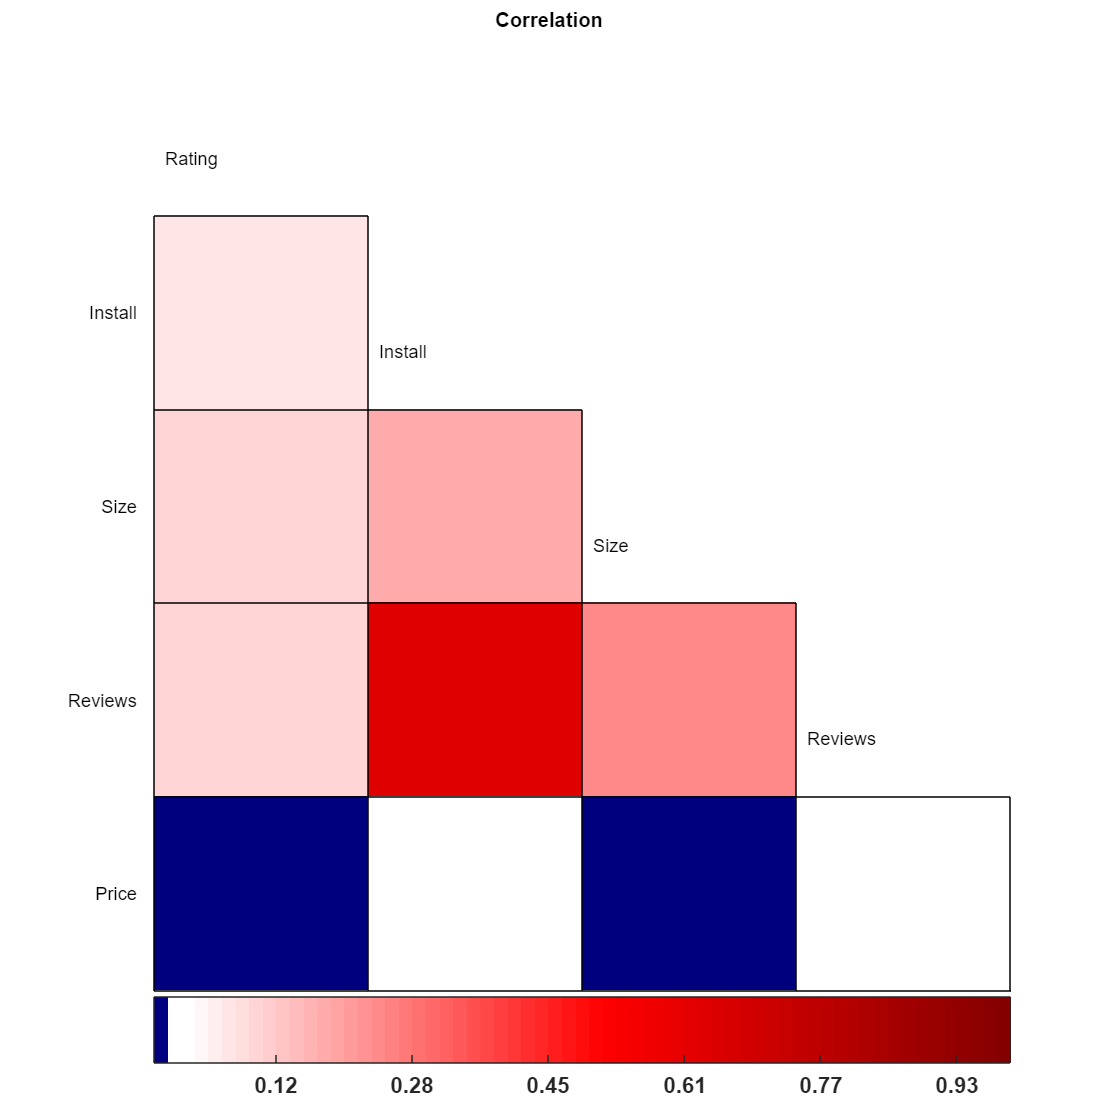

label = {'Rating','Reviews','Install','Price','Size'};
nROI = 5;
sort_ind = [1:2:nROI,2:2:nROI];
[~, h_corrmat, h_colorbar] = plot_corrmat([],... % leave timeSeries input empty, since already calculated corrmat
    'corrmat', R,... % the correlation matrix
    'title', 'Correlation',... % plot title
    'labels', label,... % correlation matrix cell labels
    'sort_ind', sort_ind,... % sort ROIs for plotting
    'label_FontSize', 10,... % long labels get cutoff with larger fonts
    'outline', 2); % outline the cells (appearance improvement)

plot3(data.Rating, data.Reviews,data.Installs, 'b.', 'markersize', 12)
xlabel('Rating')
ylabel('Reviews')
zlabel('Install')
title("Rating vs Reviews vs Install", FontSize=14)



plot3(data.Rating, data.Reviews,data.Price, 'b.', 'markersize', 12)
xlabel('Rating')
ylabel('Reviews')
zlabel('Price')
title("Rating vs Reviews vs Price", FontSize=14)

plot3(data.Rating, data.Reviews,data.Size_K, 'b.', 'markersize', 12)
xlabel('Rating')
ylabel('Reviews')
zlabel('Size(K)')
title("Rating vs Reviews vs Size (K)", FontSize=14)

plot3(data.Rating, data.Installs,data.Price, 'b.', 'markersize', 12)
xlabel('Rating')
ylabel('Installs')
zlabel('Price')
title("Rating vs Reviews vs Install", FontSize=14)

plot3(data.Rating, data.Installs,data.Size_K, 'b.', 'markersize', 12)
xlabel('Rating')
ylabel('Installs')
zlabel('Size(K)')
title("Rating vs Install vs Size(K)", FontSize=14)

plot3(data.Reviews, data.Installs,data.Price, 'b.', 'markersize', 12)
xlabel('Reviews')
ylabel('Install')
zlabel('Price')
title("Reviews vs Install vs Price", FontSize=14)

plot3(data.Reviews, data.Installs,data.Size_K, 'b.', 'markersize', 12)
xlabel('Reviews')
ylabel('Install')
zlabel('Size (K)')
title("Reviews vs Install vs Size (K)", FontSize=14)

plot3(data.Installs, data.Price,data.Size_K, 'b.', 'markersize', 12)
xlabel('Installs')
ylabel('Price')
zlabel('Size (K)')
title("Install vs Price vs Size (K)", FontSize=14)

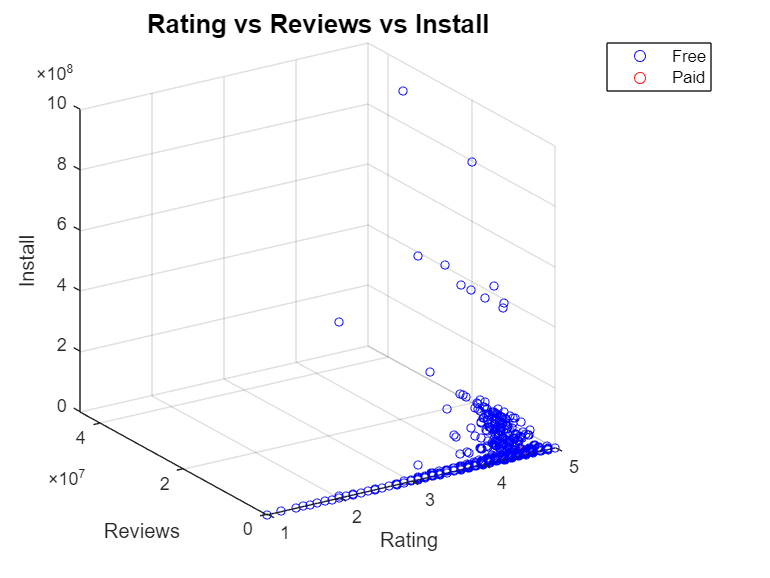



hFig = figure();
axh = axes('Parent', hFig);
hold(axh, 'all');
h1 = scatter3(data.Rating(find(data.Type == 'Free')), data.Reviews(find(data.Type == 'Free')),data.Installs(find(data.Type == 'Free')),20, 'b');
h2 =  scatter3(data.Rating(find(data.Type == 'Paid')), data.Reviews(find(data.Type == 'Paid')),data.Installs(find(data.Type == 'Paid')),20, 'r');
view(axh, -33, 22);
grid(axh, 'on');
legend(axh, [h1,h2], {'Free', 'Paid'});
xlabel('Rating')
ylabel('Reviews')
zlabel('Install')
title("Rating vs Reviews vs Install", FontSize=14)

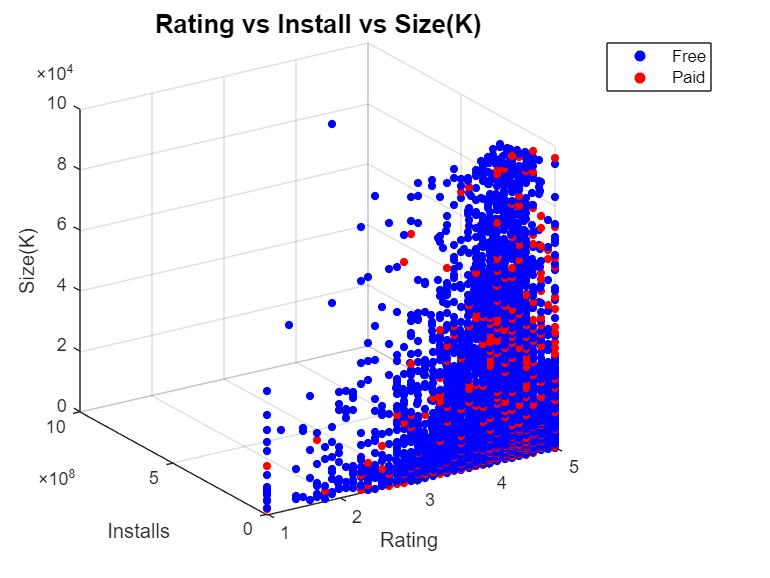

hFig = figure();
axh = axes('Parent', hFig);
hold(axh, 'all');
h1 = scatter3(data.Rating(find(data.Type == 'Free')), data.Installs(find(data.Type == 'Free')),data.Size_K(find(data.Type == 'Free')),20, 'b', 'filled');
h2 =  scatter3(data.Rating(find(data.Type == 'Paid')), data.Installs(find(data.Type == 'Paid')),data.Size_K(find(data.Type == 'Paid')),20, 'r',['fill' ...
    '']);
view(axh, -33, 22);
grid(axh, 'on');
legend(axh, [h1,h2], {'Free', 'Paid'});
xlabel('Rating')
ylabel('Installs')
zlabel('Size(K)')
title("Rating vs Install vs Size(K)", FontSize=14)

## Performing some dimension Reduction with Type

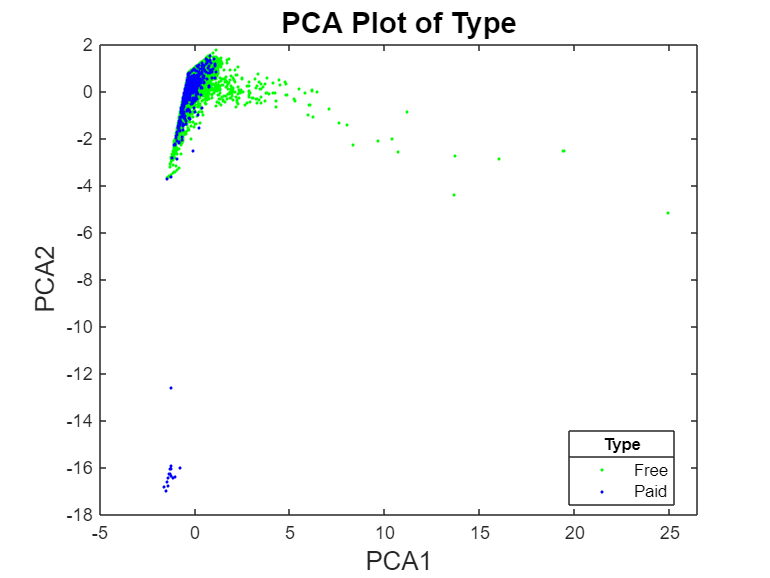

type_numData = data(:,["Type","Rating","Reviews","Installs", "Price","Size_K"] );
X = normalize(type_numData{:,2:6});
y = type_numData{:,1};
[U,S] = svds(X - mean(X,1), 2);
Y = U .* diag(S)';
figure;
gscatter(Y(:,1),Y(:,2), y)
xlabel('PCA1','fontsize', 14)
ylabel('PCA2','fontsize', 14)
title('PCA Plot of Type', 'fontsize', 16)
lgd = legend();
title(lgd, "Type")

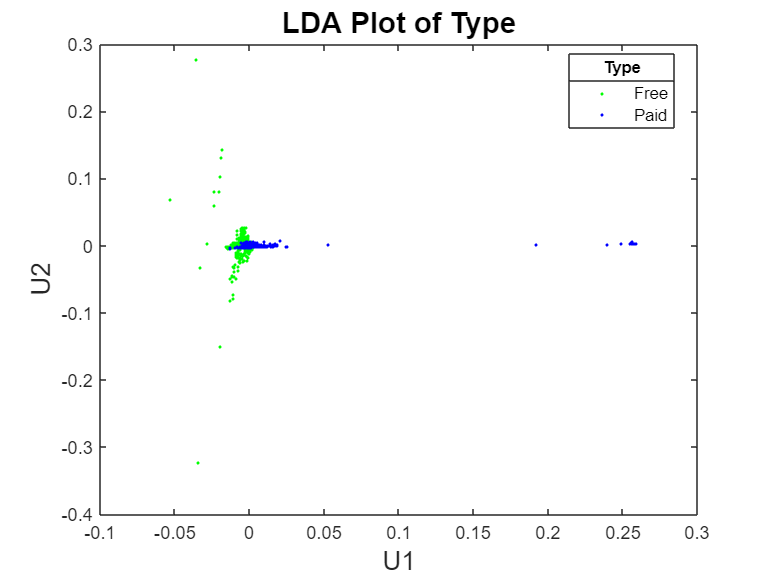

Y = PCLDA(X,y);
figure;
gscatter(Y(:,1),Y(:,2), y)
xlabel('U1','fontsize', 14)
ylabel('U2','fontsize', 14)
title('LDA Plot of Type', 'fontsize', 16)
lgd = legend();
title(lgd, "Type")

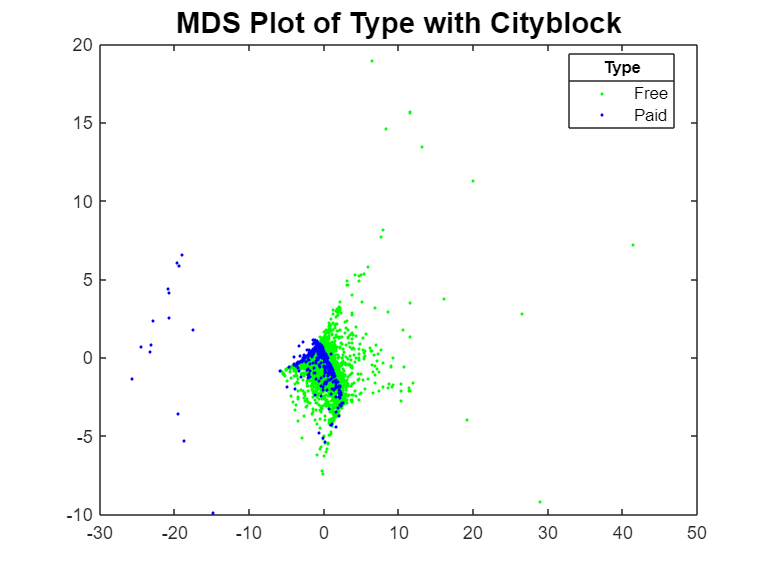

Y = cmdscale(pdist(X, 'cityblock'),2);
gscatter(Y(:,1),Y(:,2), y)
title('MDS Plot of Type with Cityblock', 'fontsize', 16)
lgd = legend();
title(lgd, "Type")

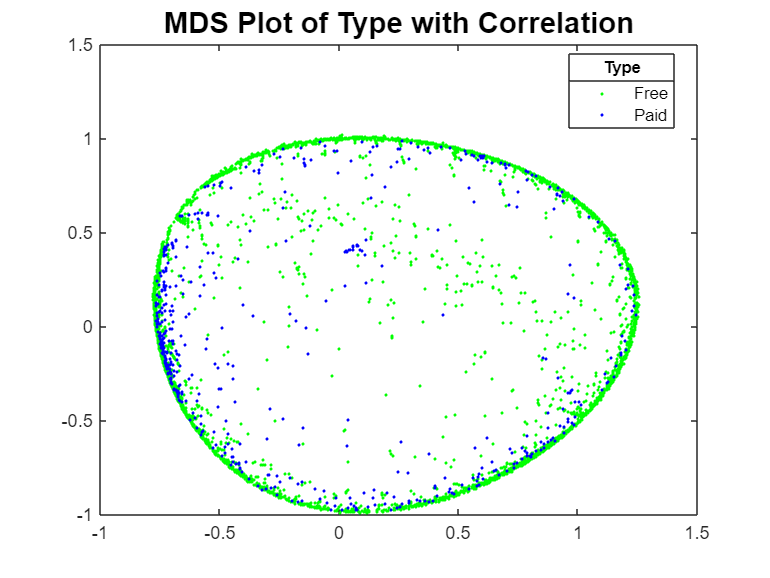

Y = cmdscale(pdist(X, 'correlation'),2);
gscatter(Y(:,1),Y(:,2), y)
title('MDS Plot of Type with Correlation', 'fontsize', 16)
lgd = legend();
title(lgd, "Type")

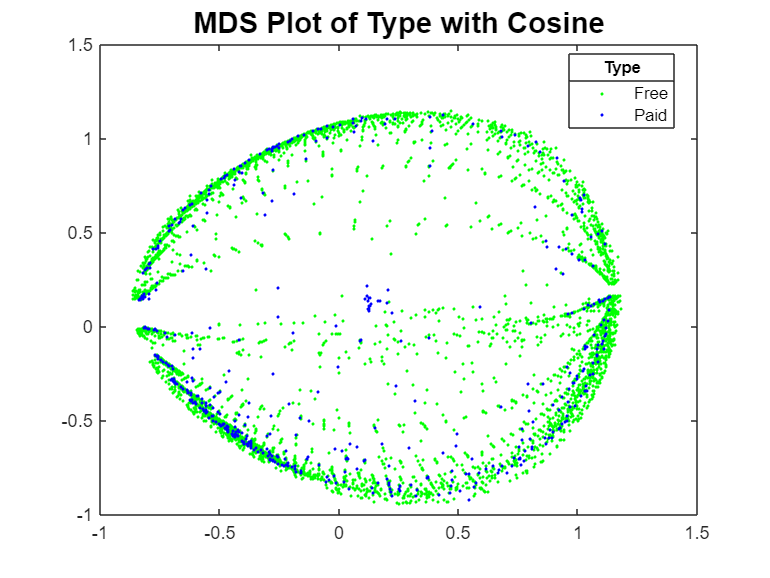

Y = cmdscale(pdist(X, 'cosine'),2);
gscatter(Y(:,1),Y(:,2), y)
title('MDS Plot of Type with Cosine', 'fontsize', 16)
lgd = legend();
title(lgd, "Type")

## with ContentRating

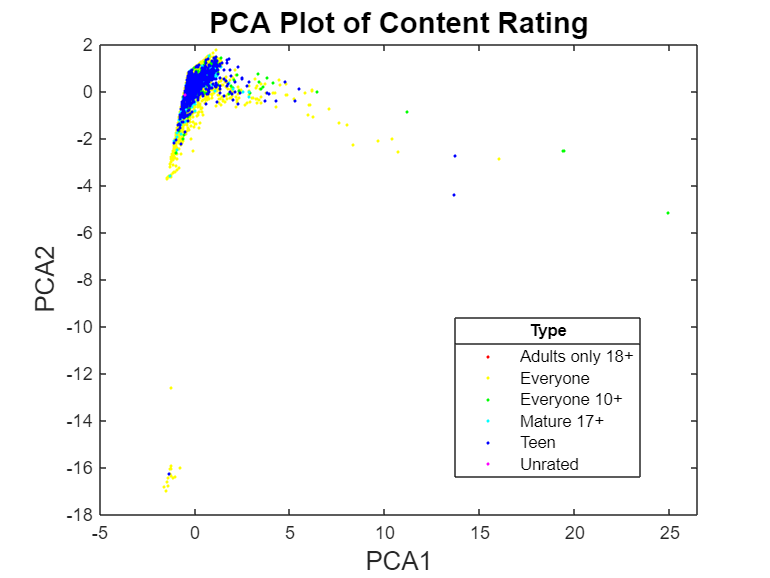

type_numData = data(:,["ContentRating","Rating","Reviews","Installs", "Price","Size_K"] );
X = normalize(type_numData{:,2:6});
y = type_numData{:,1};
[U,S] = svds(X - mean(X,1), 2);
Y = U .* diag(S)';
figure;
gscatter(Y(:,1),Y(:,2), y)
xlabel('PCA1','fontsize', 14)
ylabel('PCA2','fontsize', 14)
title('PCA Plot of Content Rating', 'fontsize', 16)
lgd = legend();
title(lgd, "Type")

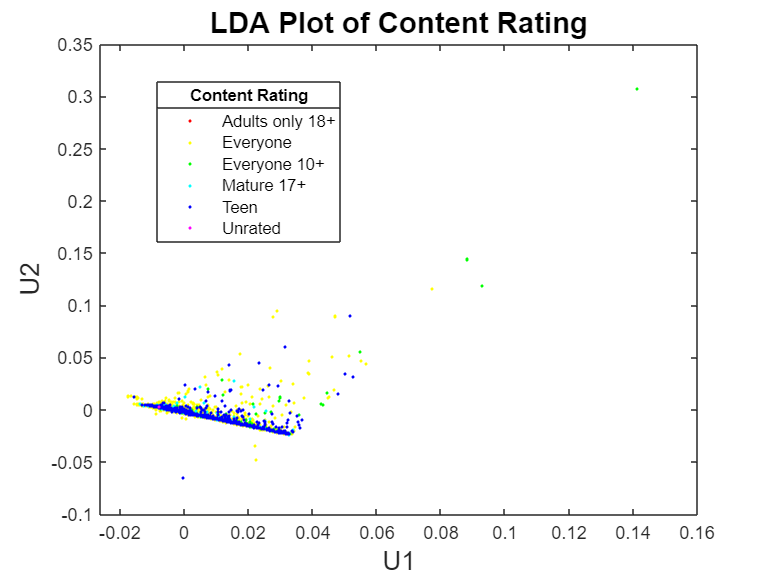

Y = PCLDA(X,y);
figure;
gscatter(Y(:,1),Y(:,2), y)
xlabel('U1','fontsize', 14)
ylabel('U2','fontsize', 14)
title('LDA Plot of Content Rating', 'fontsize', 16)
lgd = legend();
title(lgd, "Content Rating")

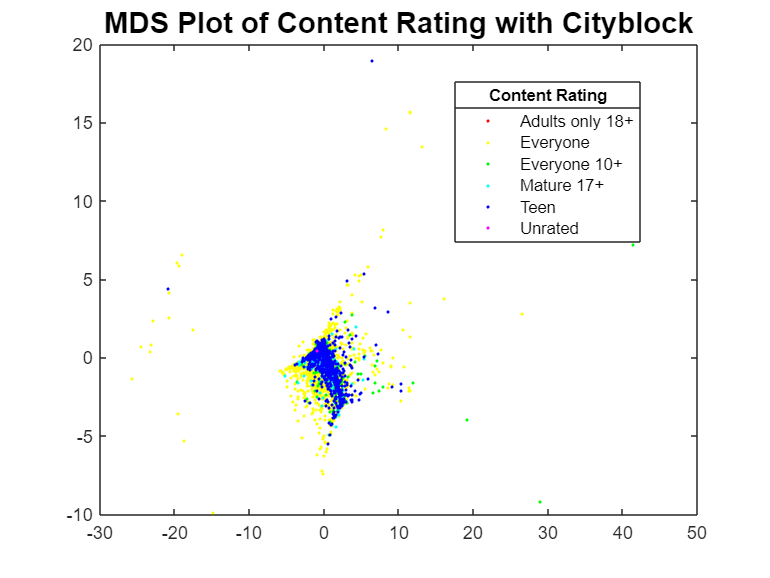

Y = cmdscale(pdist(X, 'cityblock'),2);
gscatter(Y(:,1),Y(:,2), y)
title('MDS Plot of Content Rating with Cityblock', 'fontsize', 16)
lgd = legend();
title(lgd, "Content Rating")

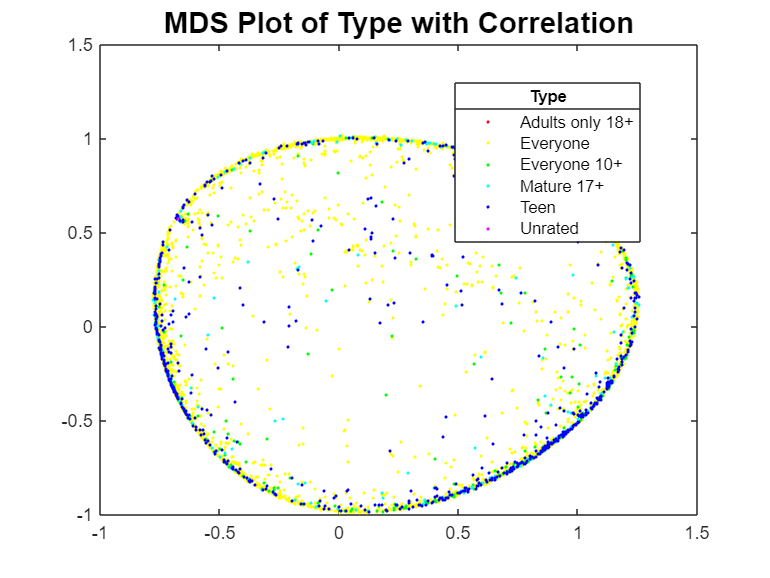

Y = cmdscale(pdist(X, 'correlation'),2);
gscatter(Y(:,1),Y(:,2), y)
title('MDS Plot of Type with Correlation', 'fontsize', 16)
lgd = legend();
title(lgd, "Content Rating")

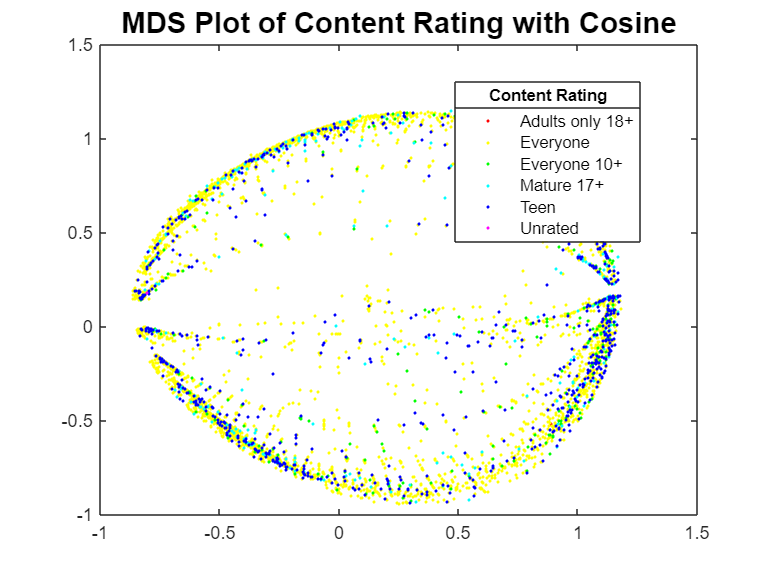

Y = cmdscale(pdist(X, 'cosine'),2);
gscatter(Y(:,1),Y(:,2), y)
title('MDS Plot of Content Rating with Cosine', 'fontsize', 16)
lgd = legend();
title(lgd, "Content Rating")

function Y = MDS(X,k,dist)
    [n,~] = size(X);
    D = pdist(X,dist);
    D = squareform(D);
    D = D.^2;
    G = zeros(n,n);
    r_sum = sum(D,2);
    c_sum = sum(D,1);
    all_sum = sum(D,'all');
    for i = 1:n
        for j = 1:n
                G(i,j) = 0.5*(0.25*r_sum(i)+0.25*c_sum(i)-(1/16)*all_sum - D(i,j));
        end
    end

    [U,S] = eigs(G,k);
    Y = U * sqrt(S);
end

function Y = PCLDA(X_,y01)
    X01 = X_ - mean(X_);
    s = svds(X01, 200);
    fracs = cumsum(s.^2)/norm(X01, 'fro')^2;
    k = find(fracs > 0.95, 1, 'first');
    [U,S] = svds(X01,k);
    Xpca = U .* diag(S)';
    c = unique(y01);
    M =[];
    m_global = mean(Xpca,1);
    for j = 1:length(c)
        digit = c(j);
        n_j = sum(y01==digit);
        m_j = mean(Xpca(y01==digit,:),1);
        Xtilde(y01==digit,:) = Xpca(y01==digit,:)-m_j;
        M(end+1,:)= sqrt(n_j)*(m_j-m_global);
    end
    S_w = Xtilde' * Xtilde;
    S_b = M'*M;
    [V, ~] = eigs(S_b, S_w,length(c));
    Y = Xpca*V;
end